newPrices = readtable('201922.csv');

newPrices_array = newPrices(:,2);
newPrices_array = table2array(newPrices_array)

newPrices_array =   109.6100
  109.7000
  108.8800
  107.6700
  108.5300
  108.7100
  108.7300
  108.1600
  108.4300
  108.5400


%OpenPrices
openingdata = newPrices(1:523,2);
openingdata = table2array(openingdata);
openingdata = openingdata';
n = length(openingdata);
disp(n);

   523



%closePrices
closingdata=newPrices(:,5);
closingdata=table2array(closingdata);
closingdata=closingdata';
n1=length(closingdata);
disp(n1);

   784



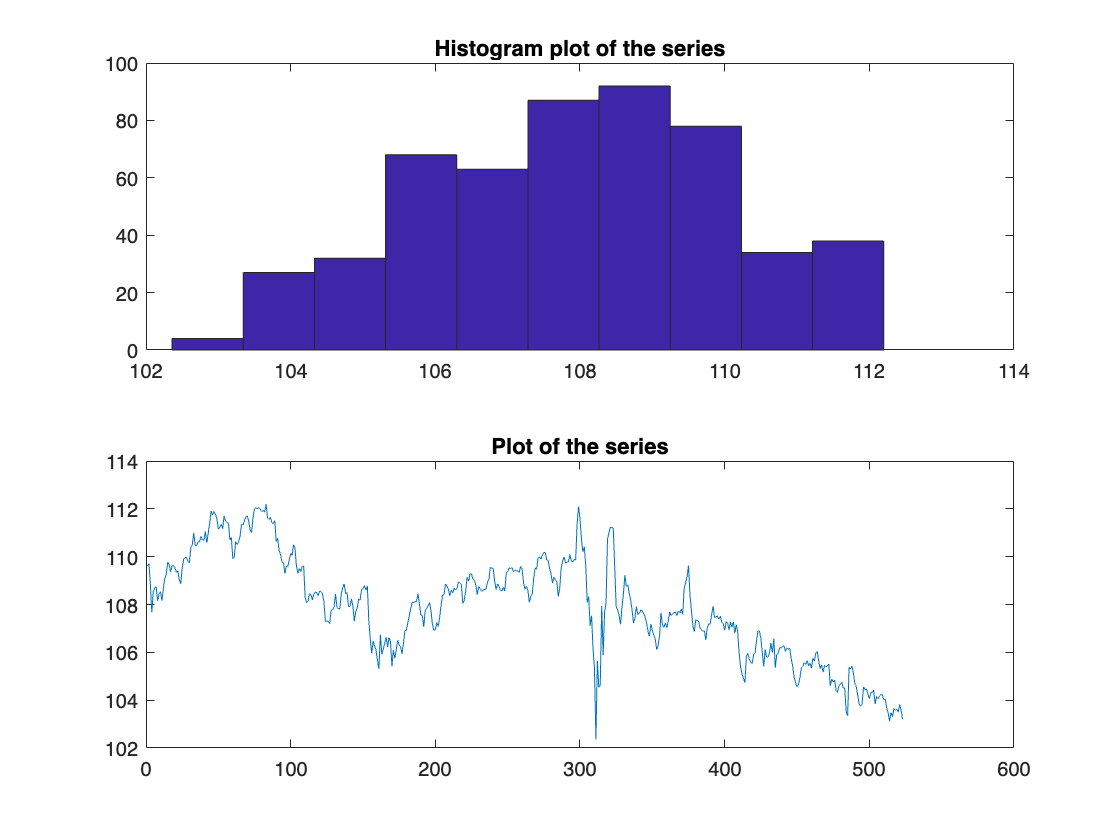

%Plotting opening data
figure
subplot(2,1,1);
hist(openingdata);
title("Histogram plot of the series");
subplot(2,1,2);
plot(openingdata);
title("Plot of the series");

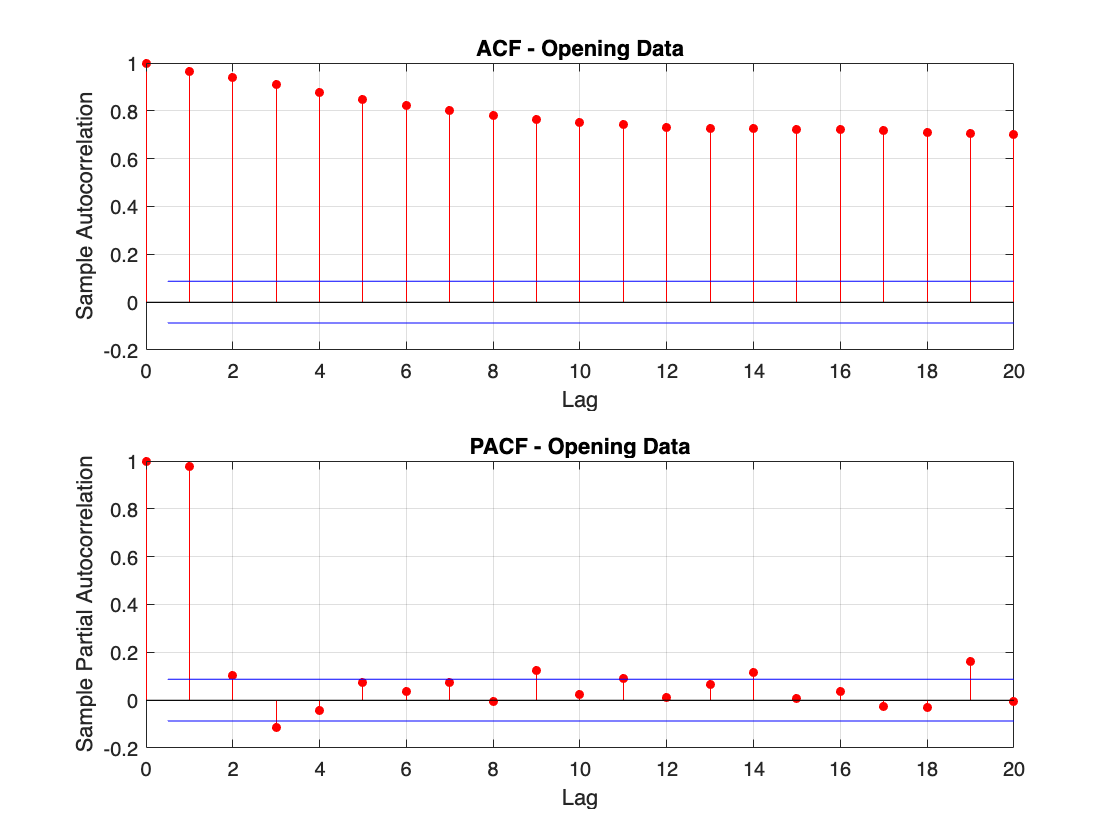

%Plotting ACF and PACF
figure
subplot(2,1,1);
autocorr(openingdata);
title("ACF - Opening Data");
subplot(2,1,2);
parcorr(openingdata);
title("PACF - Opening Data");

%Fitting Theoretical ARIMA
ARIMA_Theo= arima(0,1,0); %Theoretical ARIMA model
[ARIMA_Theo1,~,LogLikelihood]= estimate(ARIMA_Theo, openingdata');

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue 
                _________    _____________    __________    _______

    Constant    -0.012186       0.022545       -0.54054     0.58882
    Variance      0.25453      0.0062598          40.66           0



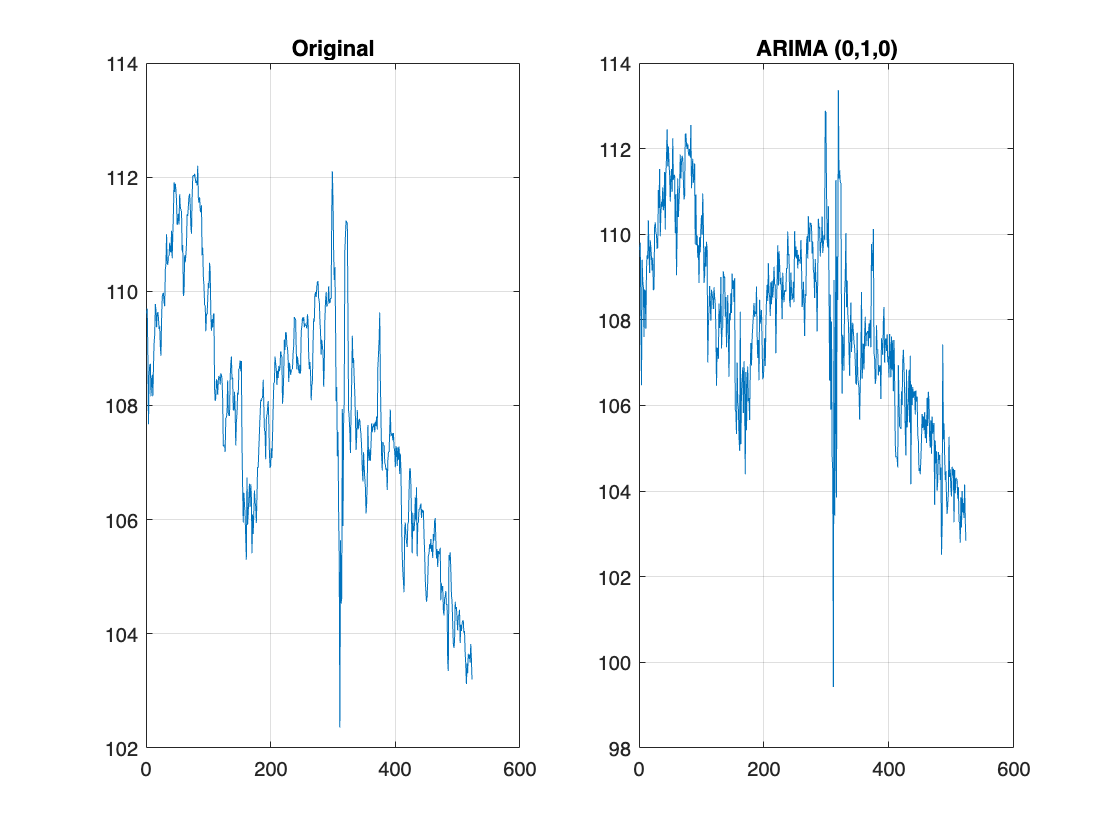



residual= infer(ARIMA_Theo1, openingdata');     % This line basically generate the difference in the 
                                                % values b/w the actual and
                                                % fitted model.
                                             
prediction= openingdata +residual';    
% Here we are basically extracting the fitted model values
%PLOT OF THE ORIGINAL AND THE FITTED MODEL
figure
subplot(1,2,1);
plot(openingdata);
title("Original");
grid on
subplot(1,2,2);
plot(prediction);
title("ARIMA (0,1,0)");
%legend('Original','ARIMA(0,1,0)','Location','best');
grid on

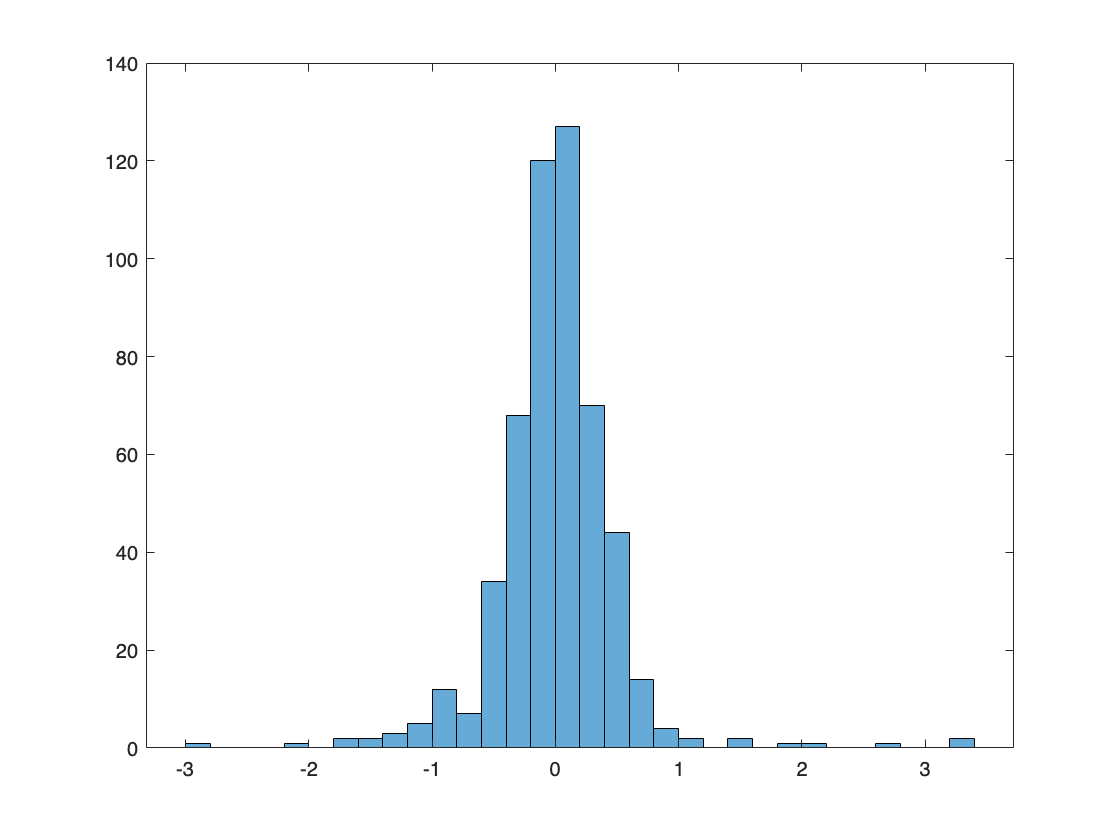

figure
histogram(residual);

 %Practical ARIMA model obtained after the AIC BIC tests

ARIMA_Prac= arima(1,0,3);                              
[ARIMA_Prac1,~,LogLikelihood2]= estimate(ARIMA_Prac, openingdata');

 
    ARIMA(1,0,3) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant       2.9114         1.4426        2.0181          0.04358
    AR{1}         0.97292       0.013393        72.645                0
    MA{1}       -0.088512       0.025162       -3.5176       0.00043539
    MA{2}         0.14872       0.037514        3.9644       7.3573e-05
    MA{3}        0.015834       0.021492       0.73673          0.46129
    Variance      0.24501      0.0073503        33.334      1.2416e-243



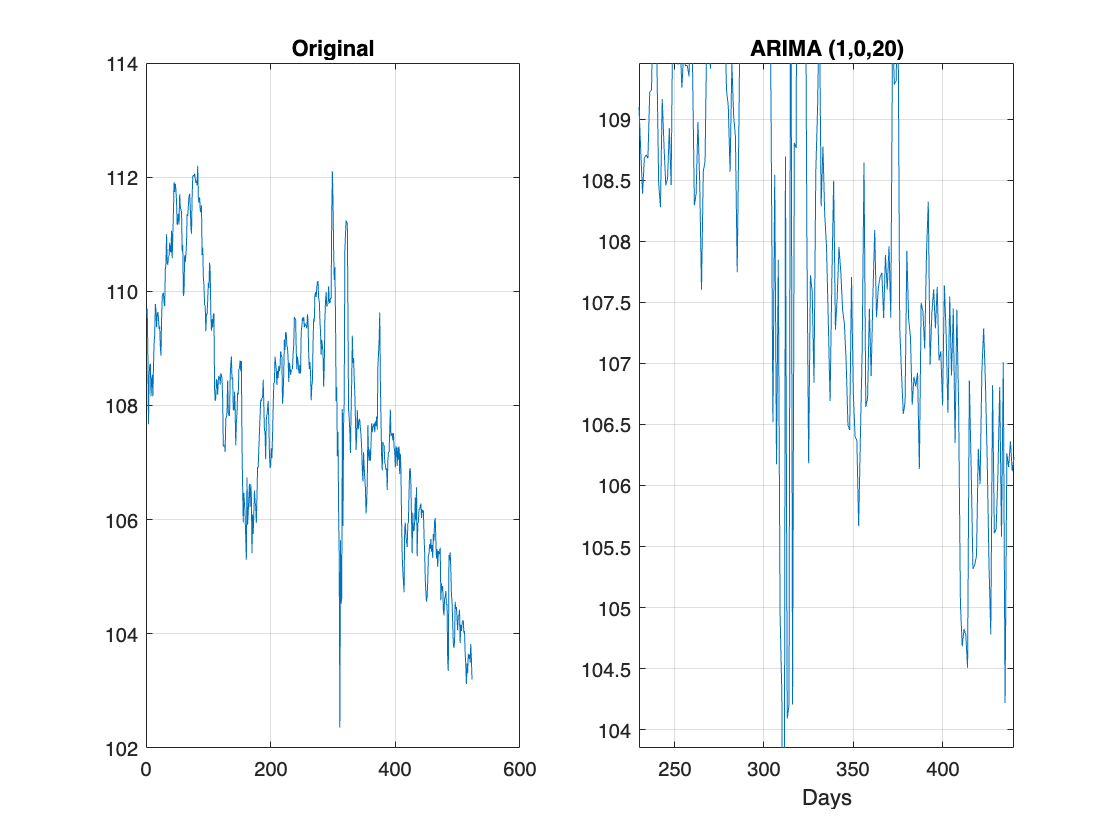


residual2= infer(ARIMA_Prac1, openingdata');        % Similar to the previous steps
prediction2= openingdata +residual2';



figure
subplot(1,2,1);
plot(openingdata);
title("Original");
grid on
subplot(1,2,2);
plot(prediction2);
title("ARIMA (1,0,20)");
grid on

subplot(1,2,2)
xlim([230 440])
ylim([103.85 109.46])
xlabel("Days")

a=newPrices_array(1:523)

a =   109.6100
  109.7000
  108.8800
  107.6700
  108.5300
  108.7100
  108.7300
  108.1600
  108.4300
  108.5400


b=newPrices_array(524:end)

b =   103.2800
  103.2400
  103.1000
  102.7200
  103.0500
  103.8100
  103.9400
  104.2600
  103.7600
  103.8800



Md=estimate(ARIMA_Prac1,a);

 
    ARIMA(1,0,3) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic    PValue
                _______    _____________    __________    ______

    Constant     2.9114          0             Inf          0   
    Variance    0.24501          0             Inf          0   



f=forecast(Md,261,'Y0',a);
disp(f)

  103.3224
  103.3519
  103.4557
  103.5651
  103.6715
  103.7750
  103.8757
  103.9736
  104.0690
  104.1617
  104.2519
  104.3397
  104.4251
  104.5082
  104.5890
  104.6677
  104.7442
  104.8187
  104.8911
  104.9616
  105.0301
  105.0968
  105.1617
  105.2249
  105.2863
  105.3461
  105.4042
  105.4608
  105.5158
  105.5694
  105.6215
  105.6722
  105.7215
  105.7694
  105.8161
  105.8615
  105.9057
  105.9487
  105.9905
  106.0312
  106.0708
  106.1093
  106.1468
  106.1833
  106.2187
  106.2533
  106.2868
  106.3195
  106.3513
  106.3822
  106.4123
  106.4416
  106.4700
  106.4977
  106.5247
  106.5509
  106.5764
  106.6013
  106.6254
  106.6489
  106.6718
  106.6940
  106.7156
  106.7367
  106.7572
  106.7771
  106.7965
  106.8154
  106.8337
  106.8516
  106.8689
  106.8858
  106.9023
  106.9183
  106.9338
  106.9490
  106.9637
  106.9780
  106.9920
  107.0056
  107.0188
  107.0316
  107.0441
  107.0563
  107.0681
  107.0796
  107.0908
  107.1017
  107.1123
  107.1226
  107.1326

pmse = mean((b-f).^2)

pmse = 13.7493

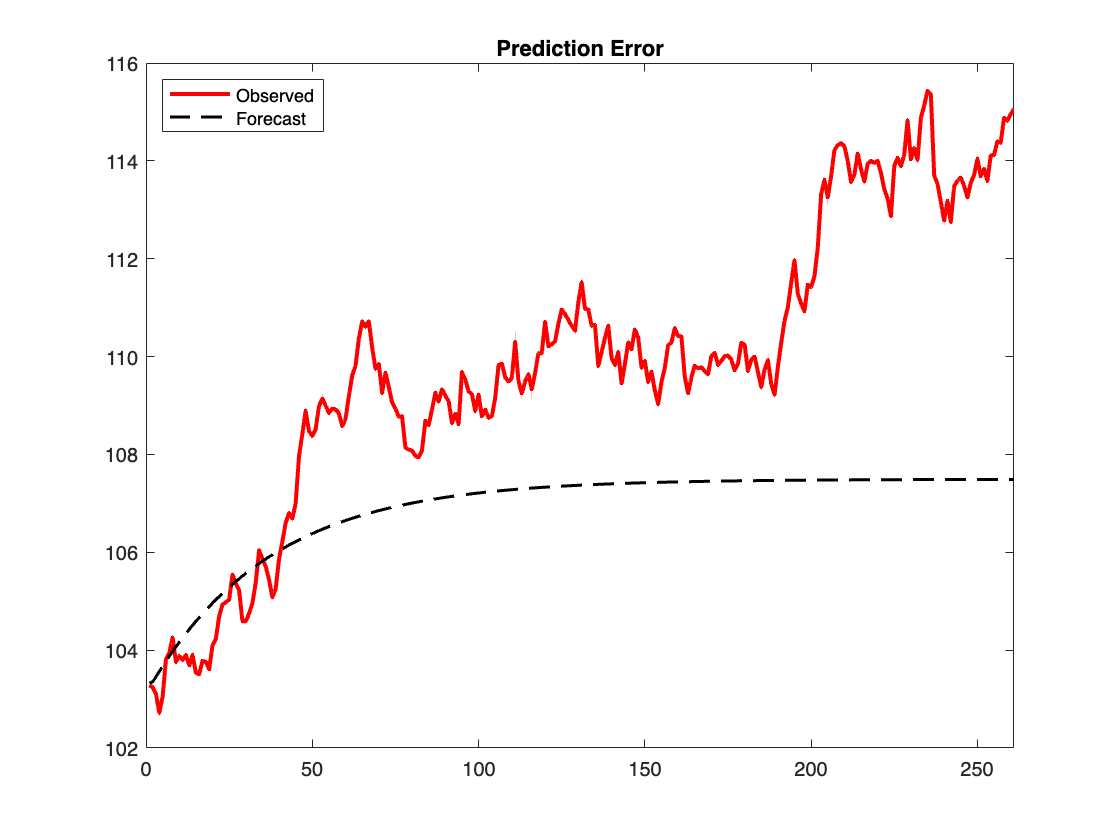


figure
plot(b,'r','LineWidth',2)
hold on
plot(f,'k--','LineWidth',1.5)
xlim([0,261])
title('Prediction Error')
legend('Observed','Forecast','Location','northwest')
hold off